# IPCC Scenario Data Visualization

This MATLAB LiveScript showcases the visualization of some of the IPCC  (Intergovernmental Panel on Climate Change) scenario data. 

The Shared Socioeconomic Pathways (SSPs) are integral to the UN climate  reports produced by the Intergovernmental Panel on Climate Change  (IPCC). They provide a set of scenarios that explore potential future  trajectories based on different socioeconomic and technological  developments. Rather than predicting specific outcomes, the SSPs offer  insights into the possible range of futures the world could experience.

These scenarios consider factors such as population growth, economic  progress, urbanization, trade, energy systems, and agriculture. They are essential for understanding how greenhouse gas emissions may evolve and impact the climate. The IPCC utilizes five key SSPs: 

- SSP1 represents a  positive scenario with sustainable development.

- SSP5 depicts  optimistic human development but relies heavily on fossil fuels.

- SSP3  and SSP4 present pessimistic visions with high levels of nationalism and global inequalities.

- SSP2 falls in the middle between SSP3 and SSP4.

The underlying data for the SSPs is from [here](https://ourworldindata.org/explorers/ipcc-scenarios?facet=none&country=SSP4+-+Baseline~SSP1+-+Baseline~SSP2+-+Baseline~SSP3+-+Baseline~SSP5+-+Baseline&Metric=Air+pollution&Sub-metric=Volatile+organic+compounds+%28VOC%29&Rate=Total&Region=Global), based on Riahi et al. (2017) 

**Reference**

Riahi, Keywan, et al. "The Shared Socioeconomic Pathways and their  energy, land use, and greenhouse gas emissions implications: An  overview." *Global environmental change* 42 (2017): 153-168.

## Installed capacity

The data  represents different energy scenarios and their corresponding installed  capacity over time. The script reads the data from a CSV file and  creates stacked area plots to illustrate the evolution of installed  capacity for various energy technologies. The visualization provides  insights into the changing landscape of energy sources in different  scenarios, highlighting the contributions of different technologies to  the overall capacity.

% Clear workspace, close figures, and clear command window
clearvars;close all;clc;
% Set the default figure renderer to painters
set(0, 'DefaultFigureRenderer', 'painters');
% Read the IPCC scenarios data from CSV file
Tab = readtable('ipcc-scenarios.csv');

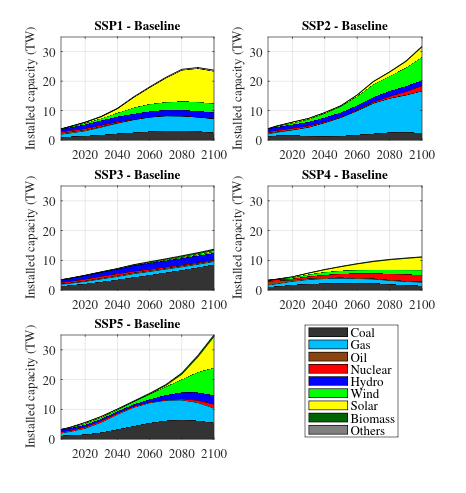

% Scenario names
scenario = {'SSP1 - Baseline', 'SSP2 - Baseline', 'SSP3 - Baseline', 'SSP4 - Baseline', 'SSP5 - Baseline'};
% Color codes for different technologies
colorCodes = {'#333333', ...   % Coal (Dark gray)
              '#00BFFF', ...   % Gas (Light blue)
              '#8B4513', ...   % Oil (Dark brown)
              '#FF0000', ...   % Nuclear (Red)
              '#0000FF', ...   % Hydro (Blue)
              '#00FF00', ...   % Wind (Green)
              '#FFFF00', ...   % Solar (Yellow)
              '#006400', ...   % Biomass (Dark green)
              '#808080'};      % Others (Gray)

% Legend labels for technologies
leg = {'Coal', 'Gas', 'Oil', 'Nuclear', 'Hydro', 'Wind', 'Solar', 'Biomass', 'Others'};

% Number of years and technologies
Nyear = 11;
Ntech = numel(leg);

% Initialize the matrix to store capacity data
T = zeros(numel(scenario), Ntech, Nyear);
time = zeros(numel(scenario),Nyear);
% Extract and organize data for each scenario and technology
for pp = 1:numel(scenario)
    indS = find(contains(Tab{:, 1}, scenario(pp)));

    time(pp, :) = Tab.Year(indS);

    T(pp, 1, :) = Tab.CoalCapacity(indS);
    T(pp, 2, :) = Tab.GasCapacity(indS);
    T(pp, 3, :) = Tab.OilCapacity(indS);
    T(pp, 4, :) = Tab.NuclearCapacity(indS);
    T(pp, 5, :) = Tab.HydropowerCapacity(indS);
    T(pp, 6, :) = Tab.WindCapacity(indS);
    T(pp, 7, :) = Tab.SolarCapacity(indS);
    T(pp, 8, :) = Tab.BiomassCapacity(indS);
    T(pp, 9, :) = Tab.OtherElectricityCapacity(indS);
end

% Create a figure for visualization
clf;
close all;
figure('position', [500, 262, 677, 716]);
tiledlayout(3, 2, "TileSpacing", "tight")

% Plot the installed capacity for each scenario
for pp = 1:numel(scenario)
    nexttile
    
    % Extract capacity data for the scenario
    z = squeeze(T(pp, :, :))' / 1000;
    
    % Create stacked area plot
    h = area(time(pp, :), z);
    
    if pp == 5
        l = legend(leg{:}, 'location', 'east');
        l.Position = [0.6551, 0.1134, 0.20, 0.2277];
    end
    
    axis tight
    grid on
    ylabel('Installed capacity (TW)')
    set(gcf, 'color', 'w')
    
    % Assign color codes to each technology
    for ii = 1:Ntech
        h(ii).FaceColor = colorCodes{ii};
    end
    
    title(scenario{pp})
    ylim([0 35])
end
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

## Greenhouse gas emissions

The following code  focuses on visualizing greenhouse gas (GHG) emissions for different IPCC  scenarios:

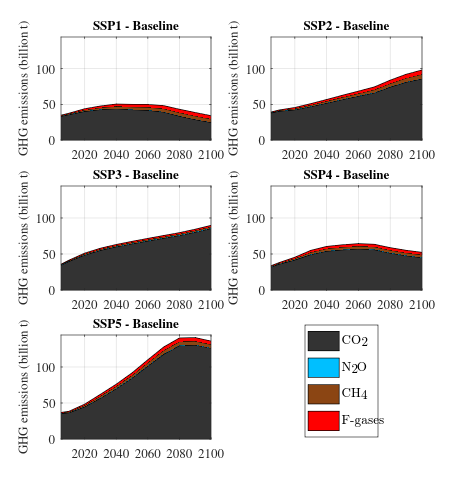

leg = {'CO$_2$ ','N$_2$O','CH$_4$ ','F-gases'};
Nyear = 11;
Ntech = numel(leg);
T = zeros(numel(scenario),Ntech,Nyear);
for pp= 1:numel(scenario),
    indS = find(contains(Tab{:,1},scenario(pp)));

    time(pp,:) = Tab.Year(indS);
    
    T(pp,1,:) = Tab.CO2Emissions(indS);
    T(pp,2,:) = Tab.MethaneEmissions(indS);
    T(pp,3,:) = Tab.F_gasEmissions(indS);
    T(pp,4,:) = Tab.F_gasEmissions(indS);
end

clf;close all;
figure('position',[500         262         677         716]);
tiledlayout(3,2,"TileSpacing","tight")
for pp= 1:numel(scenario),
    nexttile
z = squeeze(T(pp,:,:))'/1e9;
% z = z./sum(z,2,'omitnan');
h = area(time(pp,:),z);
if pp==5,
    l=legend(leg{:},'location','east');
    l.Position = [0.6551 0.1134 0.1551 0.2277];
    l.Interpreter = 'latex';

end
axis tight
grid on
ylabel('GHG emissions (billion t)')
% col=distinguishable_colors(size(T,2));
set(gcf,'color','w')
for ii=1:Ntech,h(ii).FaceColor = colorCodes{ii};end
title(scenario{pp})
ylim([0 1.025*max(reshape(max(sum(T,2))/1e9,1,[]))])
end
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

## Pollutant emissions

The code focuses on visualizing pollutant emissions for different IPCC scenarios.

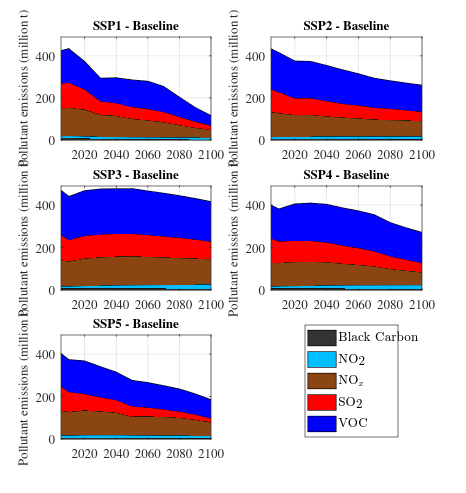

leg = {'Black Carbon ','NO$_2$','NO$_x$','SO$_2$','VOC'};
Nyear = 11;
Ntech = numel(leg);
T = zeros(numel(scenario),Ntech,Nyear);
for pp= 1:numel(scenario),
    indS = find(contains(Tab{:,1},scenario(pp)));

    time(pp,:) = Tab.Year(indS);

    T(pp,1,:) = Tab.BlackCarbonEmissions(indS);
    T(pp,2,:) = Tab.NitrousOxideEmissions(indS);
    T(pp,3,:) = Tab.NOxEmissions(indS);
    T(pp,4,:) = Tab.SulfurEmissions(indS);
    T(pp,5,:) = Tab.VOCEmissions(indS);
end

clf;close all;
figure('position',[500         262         677         716]);
tiledlayout(3,2,"TileSpacing","tight")
for pp= 1:numel(scenario),
    nexttile
z = squeeze(T(pp,:,:))'/1e6;
% z = z./sum(z,2,'omitnan');
h = area(time(pp,:),z);
if pp==5,
    
    l=legend(leg{:},'location','east');
    l.Position = [0.6551 0.1134 0.20 0.2277];
    l.Interpreter = 'latex';
    

end
axis tight
grid on
ylabel('Pollutant emissions (million t)')
% col=distinguishable_colors(size(T,2));
set(gcf,'color','w')
for ii=1:Ntech,h(ii).FaceColor = colorCodes{ii};end
title(scenario{pp})
ylim([0 1.025*max(reshape(max(sum(T,2,'omitnan'))/1e6,1,[]))])
end
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')